# Lesson 2

Written by Brenda So and Cory Nezin

# Objective

After this class, you should be able to:

- Understand how to perform vector and matrix operations

- Understand basic indexing

- Know how to use for statements

# Vector Operations

In lesson 1, we see how to make a vector with the colon operator and linspace. However, if MATLAB only allows us to use these two operations on vectors, it would be pretty useless.

As MATLAB is often used to perform numerical analysis, it would be very useful if we can input vectors into functions and use that to generate new vectors. Luckily, that's possible! Note that when you perform many of these operations, they are applied element-wise on vectors. 

x = 0:0.01:2*pi;    % create a vector
y = sin(x);         % here is a transformation from one vector to another
xlen = length(x)

xlen = 629

ylen = length(y)    % xlen and ylen are equal!

ylen = 629

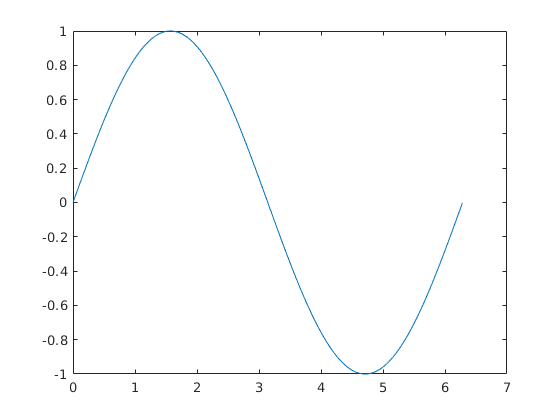


figure
plot(x,y)

## Example

Create a vector t, where t ranges from 0 to 2 millisecond with increments T = 1e-6, and create another vector y1: 


$$y_1 \left(t\right)=10cos\left(2\pi f_{0\text{ }} t+\pi \beta t^2 \right)$$


where $f_{0\text{ }} =50\text{ }Hz$ and $\beta =10\text{ }M\text{Hz}\text{ }s^{-1}$.

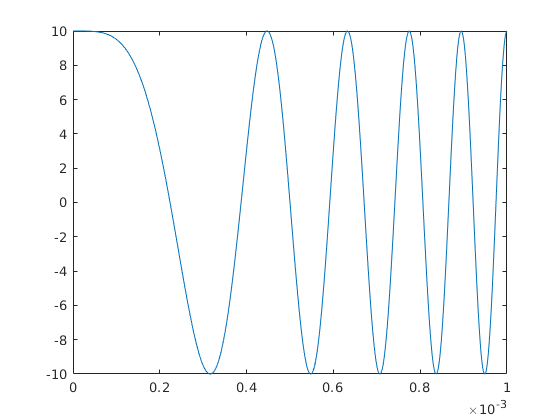

t = 0:1e-6:1e-3;

f0 = 50;
beta = 10e6;
y1 = 10*cos(2*pi*f0 + pi*beta*t.^2);


ans = -2

figure
plot(t,y1)


ans = -1.8384

# Basic Indexing in MATLAB

To inspect certain values in vectors, we can use indexing. We will delve deeper into indexing later, so for now let us  just lay down the foundation:

x = linspace(0,10,15);

ans =    -1.9596   -1.9192   -1.8788   -1.8384


x(:)    % all the elements of x as a column vector

ans = 2

x(1)    % the FIRST element of x
x(5)    % the 5th element of x
x(2:5)  % a range of elements (indexing a vector using a vector!)
x(end)  % the last element in x
A = [16 2 3 13; 5 11 10 8; 9 7 6 12; 4 14 15 1];
A(1,4)    % extract the element in row 1, column 4
A(2, :)   % extract all the elemnts from the 2nd row of A

## BE CAREFUL!

In other languages, indices start at 0, however, in MATLAB indices start at 1. Hence in MATLAB, the last index would be the length of the vector itself. Also note that MATLAB uses curly braces intead of square brackets for indexing.

# Some more vector operations

Of course, we can perform more complicated arithmetic operations on vectors, just like what we can do with scalars. Before jumping into some examples, a few notes about incrementing, appending, and preallocating:

x = 4;
x = a + 1;      % incrementing x by 1 ( there is no += or ++ in MATLAB)

v = [1 2 3 4];
v = [v 5]       % appending a value to the end of a vector. Look at note below!

**NOTE: **The appending operation above is inefficient and can (and should) be avoided by preallocating an appropriately sized vector beforehand and using indexes!

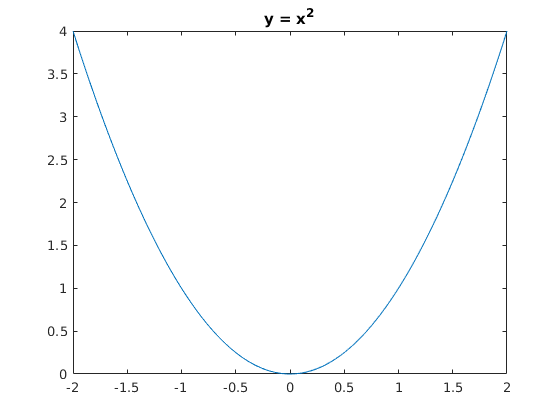

v = ones(1,5);     % preallocation

v(1:4) = [1 2 3 4];
disp(v(1:4))
v(5) = 5;
disp(v)

# Practical example of vector operations : Numerical Estimation of integrals and derivatives

Here we will look at some approximate numerical methods.

## Approximate Derivatives

x = linspace(-2,2,100);
y = x.^2;

figure
plot(x,y)
title('y = x^2')

Now, we can approximate the derivative


$$\frac{dy}{dx}=\lim_{\Delta x\to 0} \frac{y\left(x+\Delta x\right)-y\left(x\right)}{\Delta x}$$


as


$$\hat{\frac{\text{dy}}{\text{dx}}} =\frac{y\left(x+\Delta x\right)-y\left(x\right)}{\Delta x}=\frac{\Delta y}{\Delta x}$$


where$\Delta x$ is small.

An easy way to do this in MATLAB is the *diff* command which returns the difference between every pair of consecutive numbers in a vector (or each column of an array).

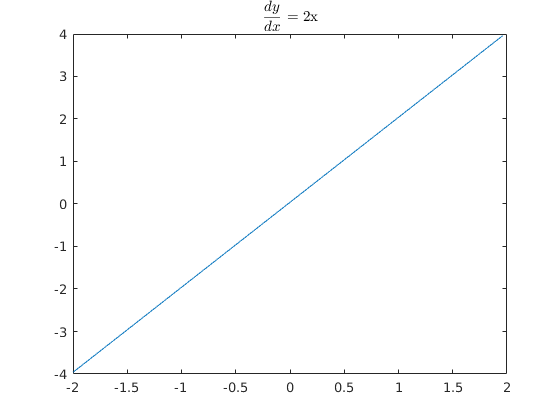

dydx = diff(y)./diff(x);

figure

% plot(x, dydx)

Because *diff *returns one less element than the original vector, this simple strategry returns an error.  Fix this by plotting against a new x, *xhat.  *Note that there are many valid ways to do this.

xhat = x(1:end-1);

Y =     0.1616    0.3168    0.4656    0.6082    0.7448    0.8754    1.0002    1.1193    1.2329    1.3411    1.4440    1.5418    1.6345    1.7224    1.8055    1.8841    1.9581    2.0277    2.0932    2.1546    2.2120    2.2655    2.3154    2.3617    2.4046    2.4442    2.4806    2.5140    2.5445    2.5722    2.5973    2.6199    2.6401    2.6581    2.6739    2.6878    2.6998    2.7101    2.7188    2.7261    2.7320    2.7368    2.7405    2.7433    2.7453    2.7466    2.7474    2.7479    2.7480    2.7480


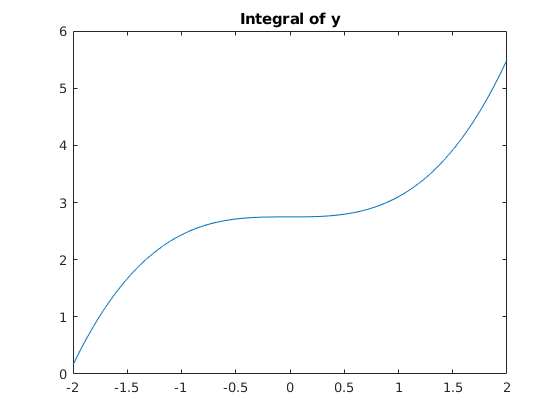


figure

plot(xhat,dydx)
title('$\displaystyle\frac{dy}{dx}$ = 2x', 'interpreter', 'latex')

## Approximate Integrals

Now suppose we want to approximate the cumulative integral of a function, i.e.


$$Y\left(u\right)=\int_c^u y\left(x\right)dx=\lim_{\Delta x\to 0} \text{  }\sum_{c+n\Delta x\text{ }\in \left\lbrack c,u\right\rbrack } y\left(c+n\Delta x\right)\Delta x\text{ }$$


Again, we can approximate this by simply dropping the limit


$$\hat{Y} =\sum_{c+n\Delta x\text{ }\in \left\lbrack c,u\right\rbrack } y\left(c+n\Delta x\right)\Delta x\text{ }$$


The *cumsum* function in MATLAB returns the running sum of a vector, i.e.


$${cumsum\left(v\right)}_{1,n} =\sum v\left(1:n\right)$$


Y = cumsum(y).*(x(2)-x(1))

yhat =     0.1552    0.1488    0.1426    0.1366    0.1306    0.1248    0.1191    0.1136    0.1082    0.1029    0.0978    0.0928    0.0879    0.0831    0.0785    0.0740    0.0697    0.0654    0.0614    0.0574    0.0536    0.0499    0.0463    0.0429    0.0396    0.0364    0.0334    0.0305    0.0277    0.0251    0.0226    0.0202    0.0180    0.0158    0.0139    0.0120    0.0103    0.0087    0.0073    0.0060    0.0048    0.0037    0.0028    0.0020    0.0013    0.0008    0.0004    0.0001    0.0000    0.0000


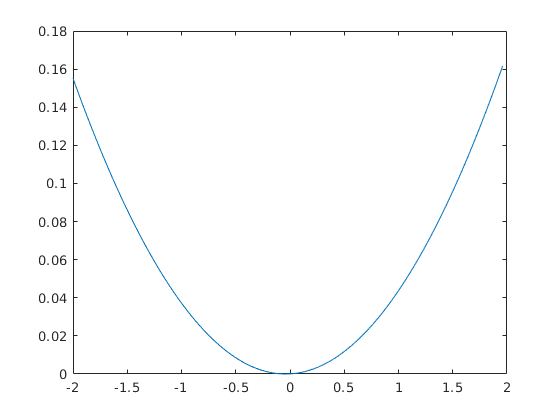

plot(x,Y)

title('Integral of y')

Now, we will use the approximate derivative to get the original function. You may need to use/create another variable for the x axis when plotting.

## Approximating the Anti-derivative

yhat = diff(Y)
plot(xhat,yhat)

# Matrix Operations

Matrices are closely related to vectors, and we have also explored some matrix operations last lesson. Now we are going to explore 3 functions that are very useful but are hard to grasp at first: reshape, meshgrid, and row-wise and column-wise operations.

## Reshape

When you are reshaping an array / matrix, the first dimension is filled first, and then the second dimension, so on and so forth

A = magic(4);

ans =     97    99
    98   100


ans =     97
    98


ex1 = reshape(A, 2, 8);
ex2 = reshape(A, 8, 2);
ex3 = reshape(A, 2, 2, 4);


x =      1     2     3


B = 1:100;

y =      1     2     3     4     5


ex4 = reshape(M,2,2,[]);     % It would create a 2*2*25 matrix

X =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


ex5 = reshape(M, [2,2,25]);  % Same as ex4

## Meshgrid

Meshgrid is quite hard to understand. Think of it as a way to replicate arrays, like the following example:

x = 1:3
y = 1:5
[X,Y] = meshgrid(x,y)

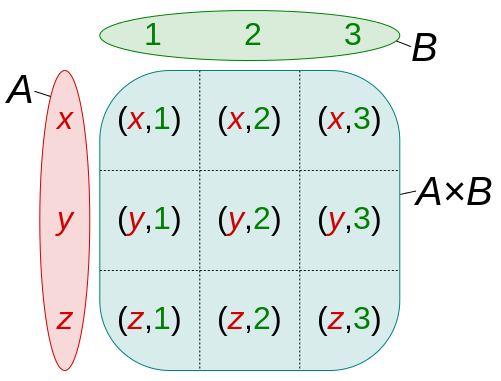

You have created two arrays A and B, note that in A, the vector a is copied row-wise, while the vector b is transposed and copied column-wise. This is useful, because when you lay one above the other, you essentially create a CARTESIAN PRODUCT, and it is useful when we need to plot a 3D graph: https://en.wikipedia.org/wiki/Cartesian_product 

Here is a more complicated example to show you when meshgrid is useful

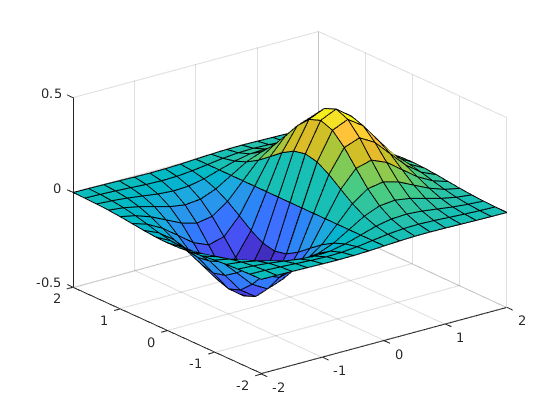

a1 = -2:0.25:2;
b1 = a1;

[A1,B1] = meshgrid(a1);

% Here we plot the surface of f(x) = x*exp^(x.^2+y.^2)
F = A1.*exp(-A1.^2-B1.^2);
surf(A1,B1,F)

## Row-wise / Column-wise operations

Besides transforming operations, there are also pre-built functions in MATLAB that allow us to obtain certain statistics. There's a lot of such functions but we are only showing a few of the more commonly used ones.

H = magic(4)     % create the magical matrix H

H =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


ans =     34    34    34    34


ans =     13     3     2    16
     8    10    11     5
    12     6     7     9
     1    15    14     4


ans =      4    14    15     1
     9     7     6    12
     5    11    10     8
    16     2     3    13


H =     13     3     2    16
     5    11    10     8
     9     7     6    12
     4    14    15     1


H =      5    11    10     8
     9     7     6    12
     4    14    15     1


sum(H,1)         % column-wise sum, note that this is by default a row vector
mean(H,1)        % mean along the columns
fliplr(H)        % flip H from left to right
flipud(H)        % flip H upside down
H(1,:) = fliplr(H(1,:)) % flip only ONE row upside down
H(1,:) = []      % delete the first column

# Control Sequence

Similar to other languages, MATLAB has *if*, *while *and *for *control sequences. *For* loops are one of the commonly used control sequences in MATLAB. We will continue the discussion of *if* and *while later *in the next lessons.

n = 1000;
D = zeros(1000);    % pre-allocation
D(1) = 1;
D(2) = 2;
tic
for i = 3:n

Elapsed time is 0.005969 seconds.


    D(i) = D(i-1)+D(i-2);
end
toc

## BE CAREFUL!

For loops are a relatively inefficient operation in MATLAB- do not use it unless it is absolutely necessary.

Instead, you will learn more about Vectorization in the next few lessons.

## Exercise: Vector Operations

% WRITEME: calculate sum of x
% WRITEME: calculate average of x
% WRITEME: calculate minimum in x
% WRITEME: calculate difference between adjacent elements in x

## Exercise: Matrix Operations

% WRITEME: Create a random 4-by-5 matrix H2 with randi that draws random numbers from the set 1:20. Use help randi  
% WRITEME: Take the sum of second column of H2
% WRITEME: Take the average of the third row of H2
% WRITEME: reshape the 4-by-5 matrix into a 2-by-2-by-5 3D array, and name the array as C
% WRITEME: Delete the second row of each layer in C